# MATLAB dependencies

% There are several things you'll first need to do before running any of the analysis below.
% 1) Have a 2016b MATLAB or more recent versions installed
% 2) Detected events -- i.e. run your imaging data through the AQuA pipeline.
% 3) Have the following files on your path: dirPlus, detectBurst, readFts2,read_mixed_csv_ForPoskanzerData
% 4) (Optional) I use the colorbrewer color schemes. They can be downloaded here:
% https://www.mathworks.com/matlabcentral/fileexchange/34087-cbrewer---colorbrewer-schemes-for-matlab
% otherwise you can change the color arguments to any RGB you want.

## Defining directories

You need to add AQuA to your path in order to use its functions

softwareDir = 'Z:/.code/AQuA/'; %AQuA path
addpath(genpath(softwareDir));

%  read features from movies and put all the information in one structure called out
datDir = 'data/processed/v26/v26.aqua.data/'; %input directory where all of your processed movies are (aqua's .mat)
outDir = 'interim/v26.interim/';

spRes = 0.57998046875; %um/pix
tres = 0.55578697729921; %sec/frame

## Read features from all movies, store in a structure called out

% you might need to rewrite parts of this function or use your own function
% for reading in the data. When I was doing this analysis, we had AQuA
% writing the output in a strucutre called res. One layer deep was a
% substructure called fts and a layer deeper into fts was substructures like
% propagation, network, etc. The output format has changed a bit
% over time, so this function might be a little outdated. 

disp(pwd)

C:\Users\camer\Box\CMH\.repos\pfc


out = readFts(datDir);

     1

below
121219_V26_54um_2x-000_video_aqua
     2

below
121219_V26_59um_2x-000_video_aqua
     3

below
121219_V26_test2-000_video_aqua
     4

below
121219_V26_test2-000_video_aqua
     5

below
121619_10min_67um_nopupil_2x-002_video_aqua
     6

below
121619_10min_67um_nopupil_2x-002_video_aqua


pp = struct2cell(dir([datDir, '**/*.mat']));
pp

pp = 6×6 cell array
    {'121219_V26_54um_2x-000_video_aqua.mat'                                                          }    {'121219_V26_59um_2x-000_video_aqua.mat'                                                          }    {'121219_V26_test2-000_video_aqua.mat'                                                          }    {'121219_V26_test2-000_video_aqua.mat'                                                                                     }    {'121619_10min_67um_nopupil_2x-002_video_aqua.mat'                                                             }    {'121619_10min_67um_nopupil_2x-002_video_aqua.mat'                                                              }
    {'C:\Users\camer\Box\CMH\.repos\pfc\data\processed\v26\v26.aqua.data\121219_V26_54um_2x-000_video'}    {'C:\Users\camer\Box\CMH\.repos\pfc\data\processed\v26\v26.aqua.data\121219_V26_59um_2x-000_video'}    {'C:\Users\camer\Box\CMH\.repos\pfc\data\processed\v26\v26.aqua.data\121219_V26_test2-000_video'}    

 pp{2,3}

ans = 'C:\Users\camer\Box\CMH\.repos\pfc\data\processed\v26\v26.aqua.data\121219_V26_test2-000_video'

 [pp{2,3}, pp{1,3}]

ans = 'C:\Users\camer\Box\CMH\.repos\pfc\data\processed\v26\v26.aqua.data\121219_V26_test2-000_video121219_V26_test2-000_video_aqua.mat'



testdirs = dir([datDir, '**/*.mat'])

testdirs = 6×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


 A = size(pp,2)

A = 6

 B = size(pp,1)

B = 6

 testdirs.date{1}

Expected one output from a curly brace or dot indexing expression, but there were 6 results.

## Now reattempting after readFts modifications

out = readFts(datDir);

     1

below
121219_V26_54um_2x-000_video_aqua
     2

below
121219_V26_59um_2x-000_video_aqua
     3

below
121219_V26_test2-000_video_aqua
     4

below
121219_V26_test2-000_video_aqua
     5

below
121619_10min_67um_nopupil_2x-002_video_aqua
     6

below
121619_10min_67um_nopupil_2x-002_video_aqua


## Detect burst periods

%this function does a lot, so take from it what you need! most likely the
%mouse running data won't be useful so feel free to comment all those parts
%out (starting with the section 'read in optoswitch data' all the way to
%the end). 
features = out;
[bursts, burstStats] = detectBurst(features, spRes, tres, outDir);

 
Current things
uT is:
   213
   214
   215
   216
   217
   218
   219
   220
   221
   222
   223
   224

Length of uT is13
 
jj is 1
i is 1
j is 2
 
Current things
uT is:
   213
   214
   215
   216
   217
   218
   219
   220
   221
   222
   223
   224

Length of uT is13
 
jj is 1
i is 1
j is 3
 
Current things
uT is:
   213
   214
   215
   216
   217
   218
   219
   220
   221
   222
   223
   224

Length of uT is13
 
jj is 1
i is 1
j is 4
 
Current things
uT is:
   213
   214
   215
   216
   217
   218
   219
   220
   221
   222
   223
   224

Length of uT is13
 
jj is 1
i is 1
j is 5
 
Current things
uT is:
   213
   214
   215
   216
   217
   218
   219
   220
   221
   222
   223
   224

Length of uT is13
 
jj is 1
i is 1
j is 6
 
Current things
uT is:
   213
   214
   215
   216
   217
   218
   219
   220
   221
   222
   223
   224

Length of uT is13
 
jj is 1
i is 1
j is 7
 
Current things
uT is:
   213
   214
   215
   216
   217
   218
   219
   220
   221
   222


Index in position 1 exceeds array bounds (must not exceed 12).

Error in detectBurst (line 47)
                if nansum(out.propGrow{jj}{i}(j,:)) == 0


%now that you can index movies based on the burst period, you can do a lot
%of analysis! I'll show an example of just one thing you can do below.

x = 2 

x = 2


disp (['x is ', num2str(x)])

x is 2


The for loop in detect burst at line 47 was going out of index because of:

    for j = 2:length(uT)+1

The +1 was pushing it past index bounds. Removing the +1 and trying again. Noted Code:

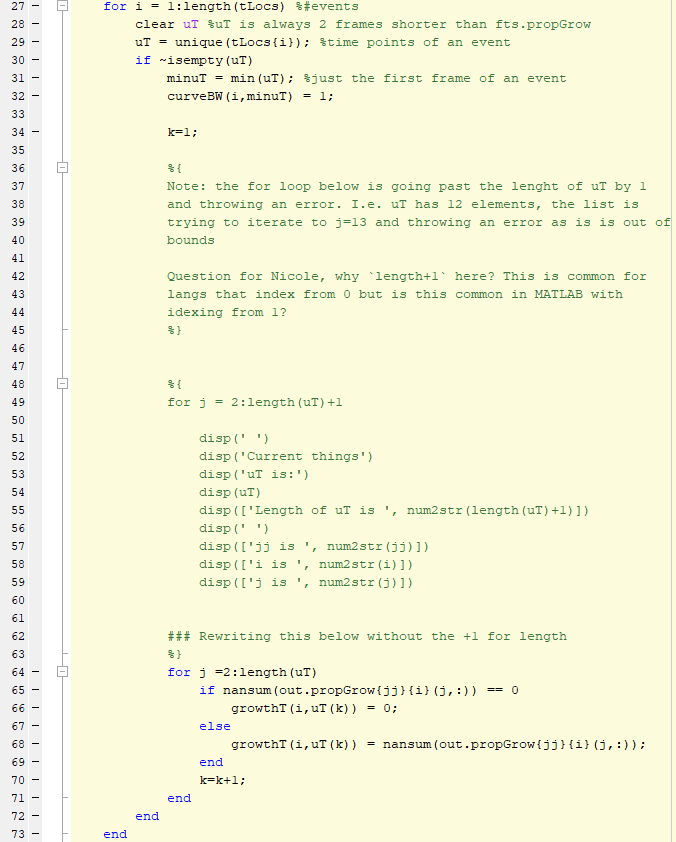

%{

            Note: the for loop below is going past the lenght of uT by 1

            and throwing an error. I.e. uT has 12 elements, the list is

            trying to iterate to j=13 and throwing an error as is is out of

            bounds

            Question for Nicole, why `length+1` here? This is common for

            langs that index from 0 but is this common in MATLAB with

            idexing from 1? 

            %}

            %{            

            for j = 2:length(uT)+1

                disp(' ')

                disp('Current things')

                disp('uT is:')

                disp(uT)

                disp(['Length of uT is ', num2str(length(uT)+1)]) 

                disp(' ')

                disp(['jj is ', num2str(jj)])

                disp(['i is ', num2str(i)])

                disp(['j is ', num2str(j)])

            ### Rewriting this below without the +1 for length

            %}

            for j =2:length(uT)

                if nansum(out.propGrow{jj}{i}(j,:)) == 0

                    growthT(i,uT(k)) = 0;

                else

                    growthT(i,uT(k)) = nansum(out.propGrow{jj}{i}(j,:));

                end

                k=k+1;

            end

features = out;
[bursts, burstStats] = detectBurst(features, spRes, tres, outDir);

Unrecognized function or variable 'bursts'.

Error in detectBurst (line 137)
    for i = 1:length(bursts{jj})

It seems like no bursts are being detected in the videos as bursts is never built inside the for loop that starts at 120 below. Trying again with disps 

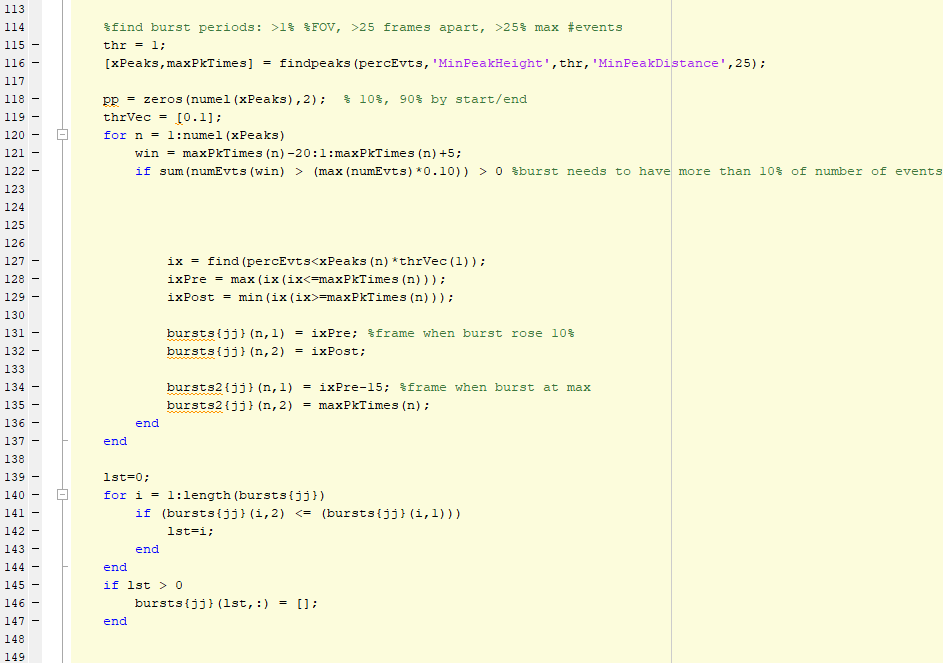

features = out;
[bursts, burstStats] = detectBurst(features, spRes, tres, outDir);

here1
xPeaks is
Num elements in xPeaks is 0
____________


Unrecognized function or variable 'bursts'.

Error in detectBurst (line 152)
    for i = 1:length(bursts{jj})

xPeaks is empty, has length 0. No peaks are being detected by findpeaks function...

Unsure if this is due to data or code. Going to try with data from Mike's video. 

Continuing here for now:

- findpeaks is from signal processing toolbox

- findpeaks is taking percEvts as arg, testing what percEvts looks like

features = out;
[bursts, burstStats] = detectBurst(features, spRes, tres, outDir);

here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here4
here

Unrecognized function or variable 'bursts'.

Error in detectBurst (line 201)
    for i = 1:length(bursts{jj})

It looks like data is being lost here

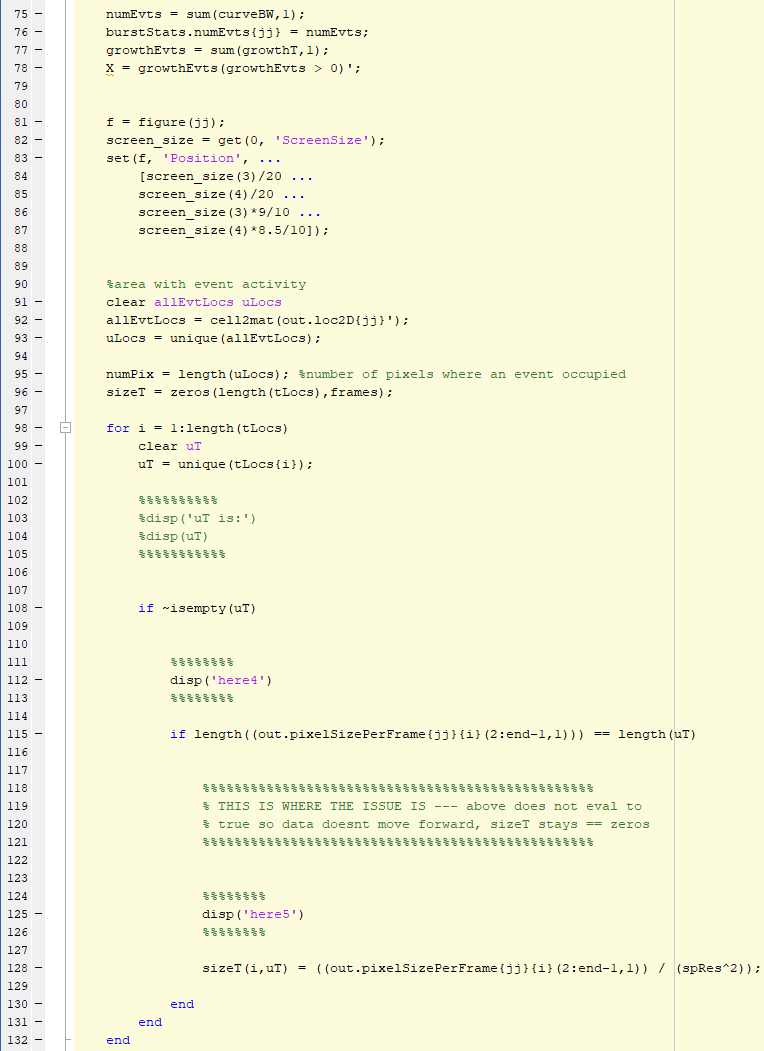

length != length so evals to false and sizeT is never added to with 

moving back from MR data as similar issues found and want to continue narrative here

features = out;
[bursts, burstStats] = detectBurst(features, spRes, tres, outDir);

allEvtLocs:
       47636
       47637
       48139
       48640
       48641
       48642
       48643
       49138
       49140
       49141

uLocs:
         836
        1127
        1338
        1628
        1629
        1841
        1842
        2130
        2131
        2132

tlocs{1}(1:10)
   581
   581
   581
   581
   581
   581
   581
   581
   581
   581

uT #1 is:
   581
   582
   583
   584
   585
   586
   587
   588
   589
   590
   591
   592
   593
   594
   595
   596
   597
   598
   599
   600
   601
   602
   603
   604
   605
   606
   607
   608
   609
   610
   611
   612
   613
   614
   615
   616
   617

here4
length((out.pixelSizePerFrame{jj}{i}(2:end-1,1)))
    35

length(uT)
    37

here4
length((out.pixelSizePerFrame{jj}{i}(2:end-1,1)))
    28

length(uT)
    30

here4
length((out.pixelSizePerFrame{jj}{i}(2:end-1,1)))
    34

length(uT)
    36

here4
length((out.pixelSizePerFrame{jj}{i}(2:end-1,1)))
    66

length(uT)
    68

here4
length((out.pixelSizePerF

Unrecognized function or variable 'bursts'.

Error in detectBurst (line 221)
    for i = 1:length(bursts{jj})

Note that the two lengths always -2 diff

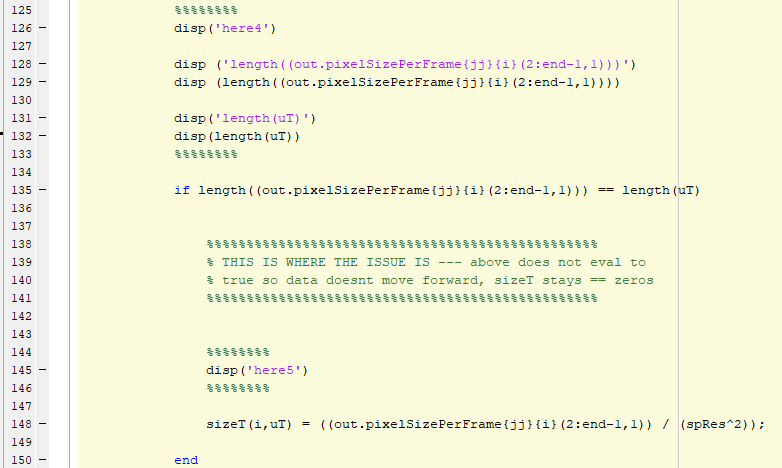

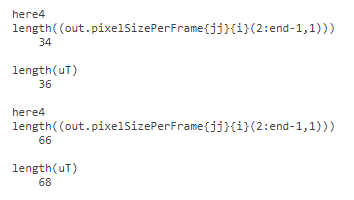

This looks like it has to do with calling (2:end-1,1) .. why is this called this way

May be related to line 28

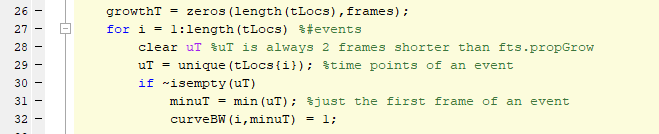

and from an older iteration.

Attempting to change line 135 above to 

features = out;
[bursts, burstStats] = detectBurst(features, spRes, tres, outDir);

allEvtLocs:
       47636
       47637
       48139
       48640
       48641
       48642
       48643
       49138
       49140
       49141

uLocs:
         836
        1127
        1338
        1628
        1629
        1841
        1842
        2130
        2131
        2132

tlocs{1}(1:10)
   581
   581
   581
   581
   581
   581
   581
   581
   581
   581

uT #1 is:
   581
   582
   583
   584
   585
   586
   587
   588
   589
   590
   591
   592
   593
   594
   595
   596
   597
   598
   599
   600
   601
   602
   603
   604
   605
   606
   607
   608
   609
   610
   611
   612
   613
   614
   615
   616
   617

here4
length((out.pixelSizePerFrame{jj}{i}(2:end-1,1)))
    35

length(uT)
    37

here5


Unable to perform assignment because the size of the left side is 1-by-37 and the size of the right side is 35-by-1.

Error in detectBurst (line 157)
                sizeT(i,uT) = ((out.pixelSizePerFrame{jj}{i}(2:end-1,1)) / (spRes^2));

need to change the line below as well

features = out;
[bursts, burstStats] = detectBurst(features, spRes, tres, outDir);

allEvtLocs:
       47636
       47637
       48139
       48640
       48641
       48642
       48643
       49138
       49140
       49141

uLocs:
         836
        1127
        1338
        1628
        1629
        1841
        1842
        2130
        2131
        2132

length tlocs is: 795
tlocs{1}(1:10)
   581
   581
   581
   581
   581
   581
   581
   581
   581
   581

uT #1 is:
   581
   582
   583
   584
   585
   586
   587
   588
   589
   590
   591
   592
   593
   594
   595
   596
   597
   598
   599
   600
   601
   602
   603
   604
   605
   606
   607
   608
   609
   610
   611
   612
   613
   614
   615
   616
   617

sizeT is:
   795   870

sizeEvts are:
   1.0e+03 *

  Columns 1 through 3

    0.0372    0.3917    0.4757

  Columns 4 through 6

    0.4600    0.4653    0.5069

  Columns 7 through 9

    0.4786    0.4251    0.3575

  Columns 10 through 12

    0.3337    0.3040    0.2780

  Columns 13 through 15

    0.2594    0.2505    0.2252

  Columns 1

Array indices must be positive integers or logical values.

Error in detectBurst (line 215)
        if sum(numEvts(win) > (max(numEvts)*0.10)) > 0 %burst needs to have more than 10% of number of events

Success! Kinda

Ok, new problem.. looks like there is an indexing thing at line 215

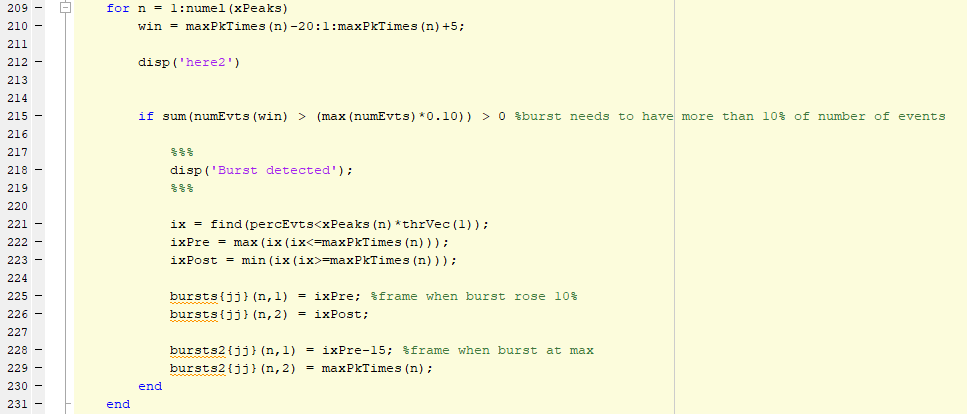

[bursts, burstStats] = detectBurst(features, spRes, tres, outDir);

allEvtLocs:
       47636
       47637
       48139
       48640
       48641
       48642
       48643
       49138
       49140
       49141

uLocs:
         836
        1127
        1338
        1628
        1629
        1841
        1842
        2130
        2131
        2132

length tlocs is: 795
tlocs{1}(1:10)
   581
   581
   581
   581
   581
   581
   581
   581
   581
   581

uT #1 is:
   581
   582
   583
   584
   585
   586
   587
   588
   589
   590
   591
   592
   593
   594
   595
   596
   597
   598
   599
   600
   601
   602
   603
   604
   605
   606
   607
   608
   609
   610
   611
   612
   613
   614
   615
   616
   617

sizeT is:
   795   870

sizeEvts are:
   1.0e+03 *

  Columns 1 through 3

    0.0372    0.3917    0.4757

  Columns 4 through 6

    0.4600    0.4653    0.5069

  Columns 7 through 9

    0.4786    0.4251    0.3575

  Columns 10 through 12

    0.3337    0.3040    0.2780

  Columns 13 through 15

    0.2594    0.2505    0.2252

  Columns 1

Array indices must be positive integers or logical values.

Error in detectBurst (line 222)
        disp(numEvts(win))

It looks like 'win' should be an index like (-14:5)

Not a range ie. (-14,-13,-12.......4,5)

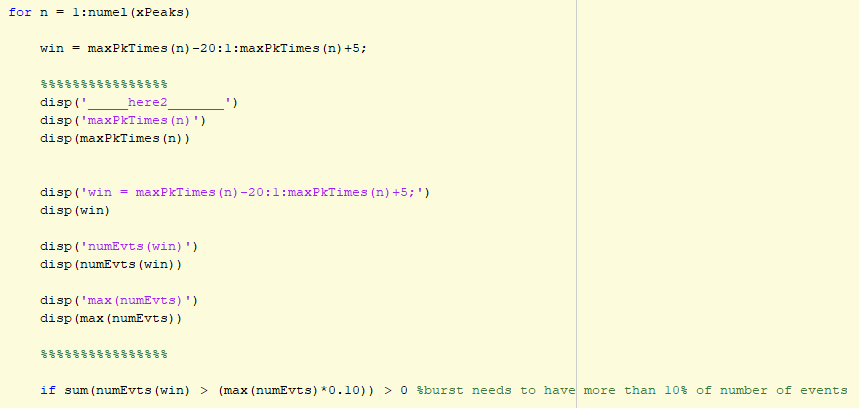

otherwise why call numEvts(win) ie numEvts in window

Or is it just that (-) numbers are being called as indicies... 

trying with this:

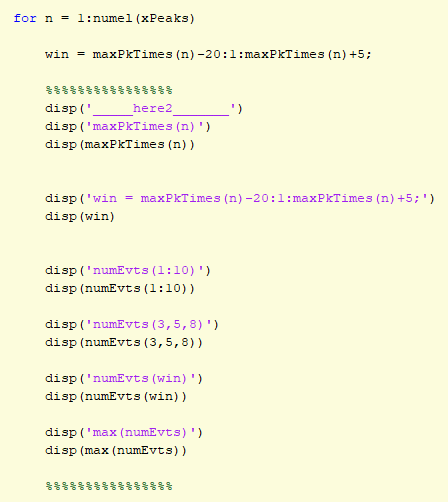

[bursts, burstStats] = detectBurst(features, spRes, tres, outDir);

allEvtLocs:
       47636
       47637
       48139
       48640
       48641
       48642
       48643
       49138
       49140
       49141

uLocs:
         836
        1127
        1338
        1628
        1629
        1841
        1842
        2130
        2131
        2132

length tlocs is: 795
tlocs{1}(1:10)
   581
   581
   581
   581
   581
   581
   581
   581
   581
   581

uT #1 is:
   581
   582
   583
   584
   585
   586
   587
   588
   589
   590
   591
   592
   593
   594
   595
   596
   597
   598
   599
   600
   601
   602
   603
   604
   605
   606
   607
   608
   609
   610
   611
   612
   613
   614
   615
   616
   617

sizeT is:
   795   870

sizeEvts are:
   1.0e+03 *

  Columns 1 through 3

    0.0372    0.3917    0.4757

  Columns 4 through 6

    0.4600    0.4653    0.5069

  Columns 7 through 9

    0.4786    0.4251    0.3575

  Columns 10 through 12

    0.3337    0.3040    0.2780

  Columns 13 through 15

    0.2594    0.2505    0.2252

  Columns 1

Array indices must be positive integers or logical values.

Error in detectBurst (line 237)
        disp(numEvts(win))

changing this did not work 

        %%%%

        % Changing the line below to give a window (1,10) rather than a

        % range (1,2,3....9,10) as it is being called to index 

        %

        %### win = maxPkTimes(n)-20:1:maxPkTimes(n)+5;

        %

        % Note this didn't work as indecies still negative. returning to

        % above

        %$$$ win = maxPkTimes(n)-20:maxPkTimes(n)+5; 

Going back, need to figure out what max pk times should look like. i.e. is it expected to be >20 always? Seems unlikely as is the output of findpeaks

[https://www.mathworks.com/help/signal/ref/findpeaks.html?searchHighlight=findpeaks&s_tid=doc_srchtitle](https://www.mathworks.com/help/signal/ref/findpeaks.html?searchHighlight=findpeaks&s_tid=doc_srchtitle)

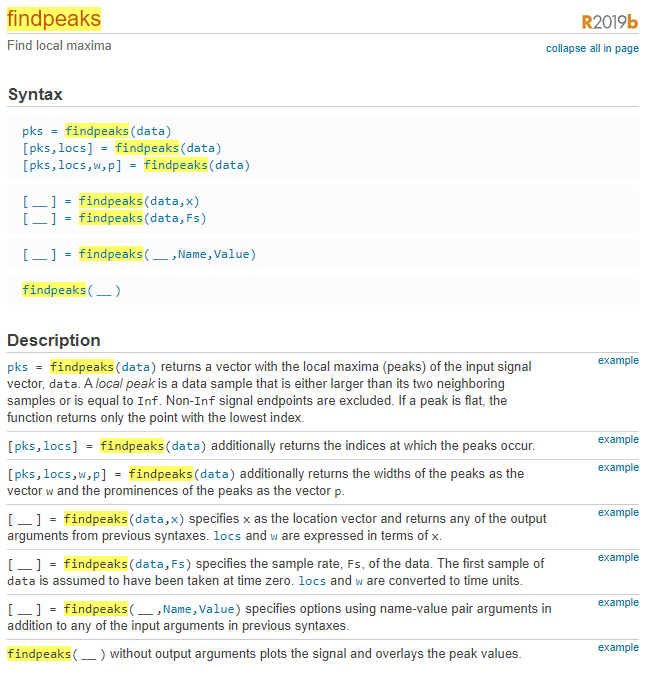

There can obviously be less than 20 peaks it seems. Basic illustration from link^

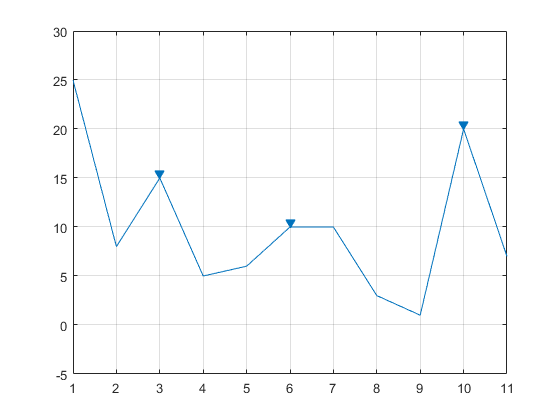

am going to try plotting percEvts to see what data looks like 

allEvtLocs:
       47636
       47637
       48139
       48640
       48641
       48642
       48643
       49138
       49140
       49141

uLocs:
         836
        1127
        1338
        1628
        1629
        1841
        1842
        2130
        2131
        2132

length tlocs is: 795
tlocs{1}(1:10)
   581
   581
   581
   581
   581
   581
   581
   581
   581
   581

uT #1 is:
   581
   582
   583
   584
   585
   586
   587
   588
   589
   590
   591
   592
   593
   594
   595
   596
   597
   598
   599
   600
   601
   602
   603
   604
   605
   606
   607
   608
   609
   610
   611
   612
   613
   614
   615
   616
   617

sizeT is:
   795   870

sizeEvts are:
   1.0e+03 *

  Columns 1 through 3

    0.0372    0.3917    0.4757

  Columns 4 through 6

    0.4600    0.4653    0.5069

  Columns 7 through 9

    0.4786    0.4251    0.3575

  Columns 10 through 12

    0.3337    0.3040    0.2780

  Columns 13 through 15

    0.2594    0.2505    0.2252

  Columns 1

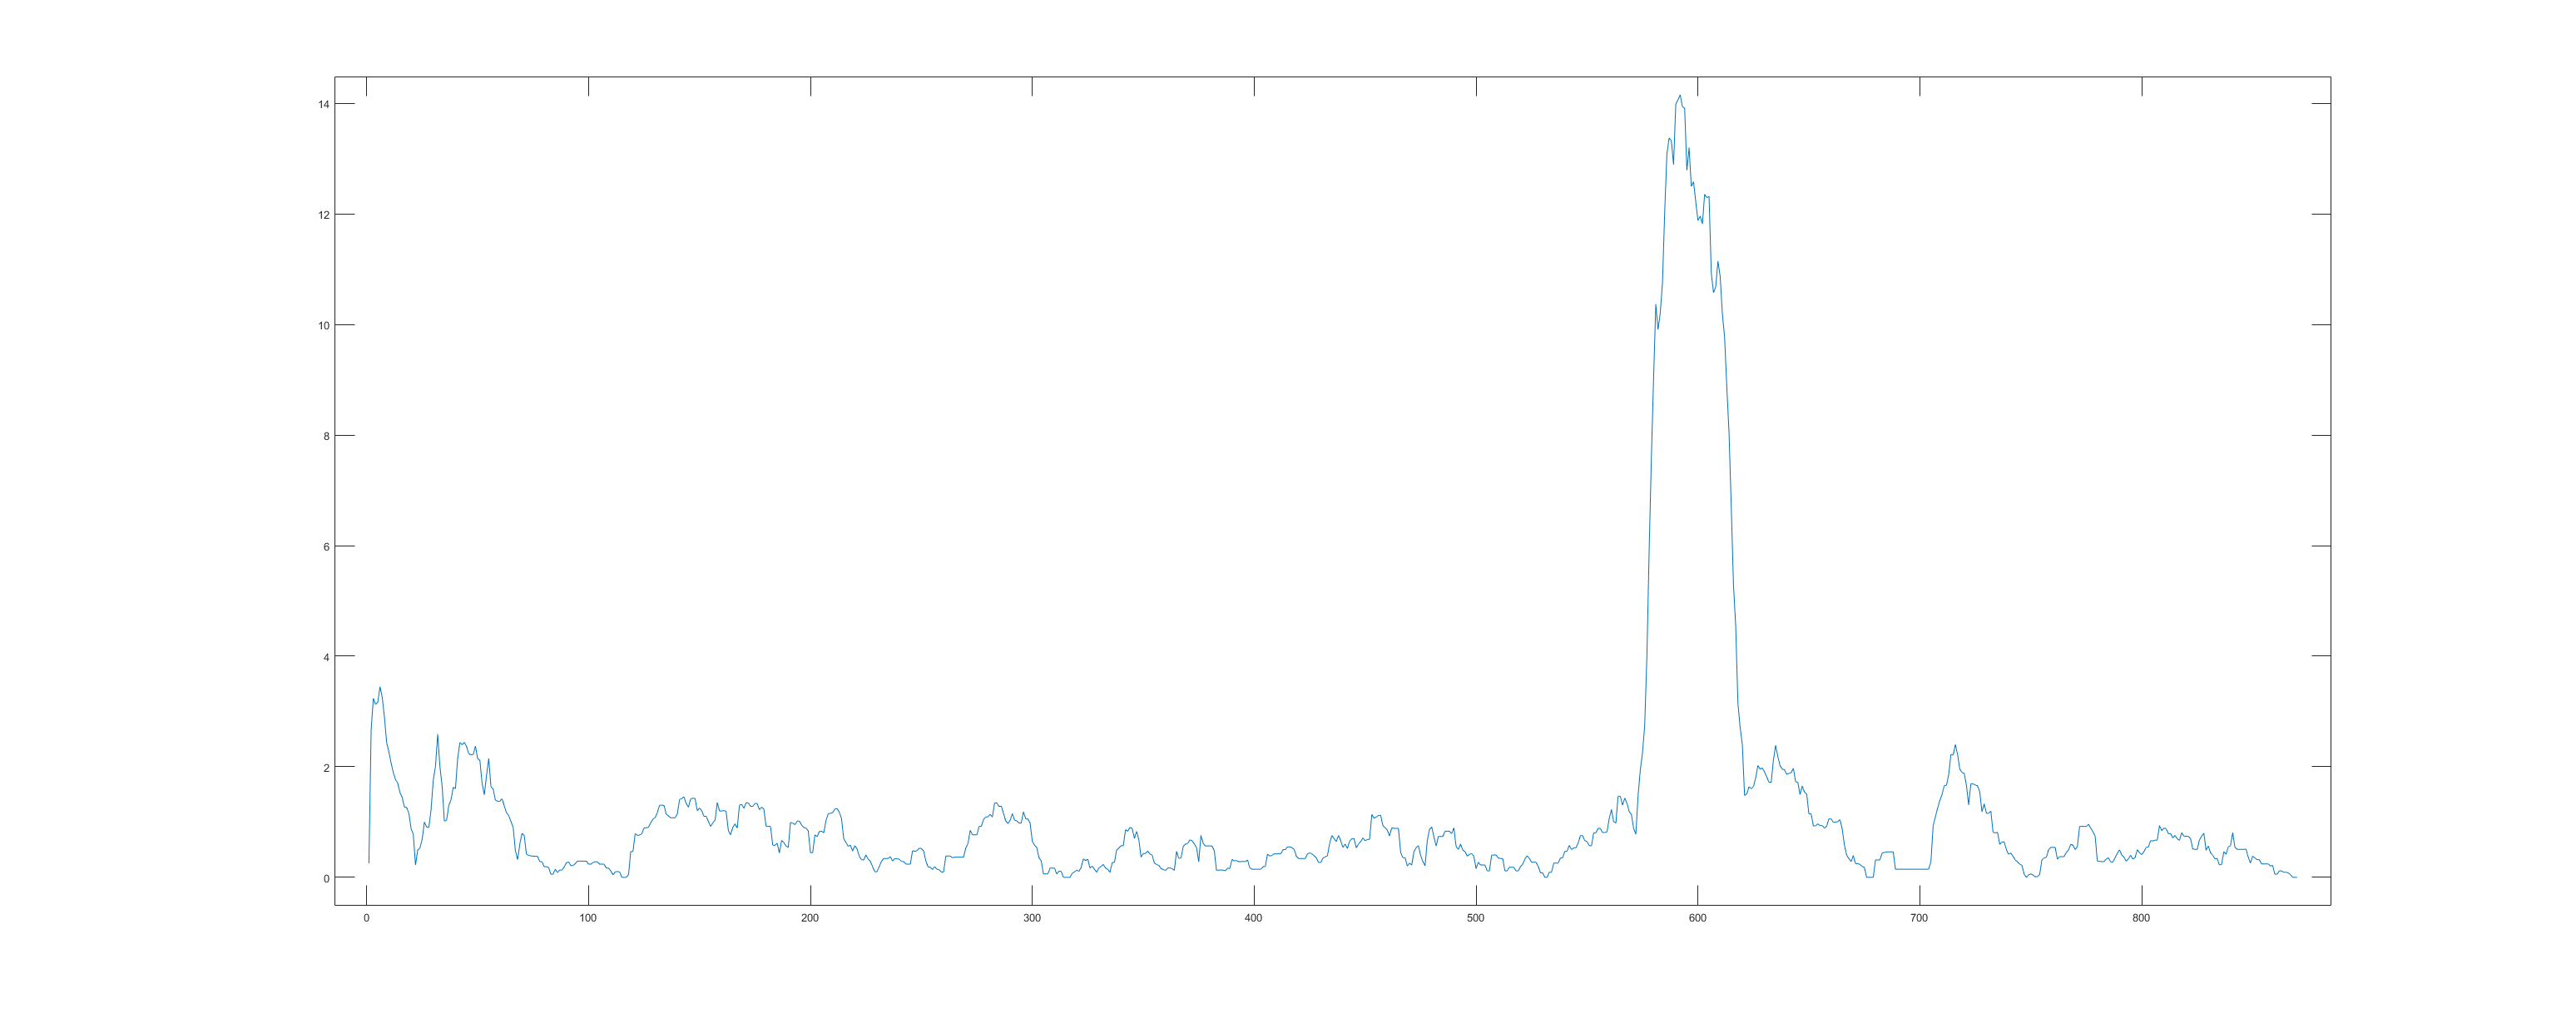

maxPkTimes(n)
     6

win = maxPkTimes(n)-20:1:maxPkTimes(n)+5;
   -14
   -13
   -12
   -11
   -10
    -9
    -8
    -7
    -6
    -5
    -4
    -3
    -2
    -1
     0
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10
    11

class / type of win:
double
numEvts(1:10)
  Columns 1 through 5

     4    25     7     9     2

  Columns 6 through 10

     8     4     2     3     1

numEvts(win)


Array indices must be positive integers or logical values.

Error in detectBurst (line 251)
        disp(numEvts(win))

[bursts, burstStats] = detectBurst(features, spRes, tres, outDir);

percEvts looks right

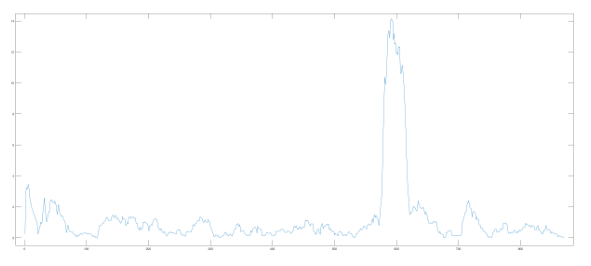

by eye there is a big burst at that point in the video.. 

Investigating what maxPkTimes looks like

[bursts, burstStats] = detectBurst(features, spRes, tres, outDir);

_____here2_______
___Burst detected____
All burst event times (maxPkTimes)
  Columns 1 through 5

     6    32    61   143   171

  Columns 6 through 10

   212   283   453   564   592

  Columns 11 through 13

   635   664   716

n is
     1

win is
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10
    11
    12
    13
    14
    15
    16
    17
    18
    19
    20
    21
    22
    23
    24
    25

numEvts(win)
     4
    25
     7
     9
     2
     8
     4
     2
     3
     1
     0
     2
     1
     2
     2
     1
     3
     1
     0
     0
     0
     0
     1
     1
     2

_____here2_______
___Burst detected____
All burst event times (maxPkTimes)
  Columns 1 through 5

     6    32    61   143   171

  Columns 6 through 10

   212   283   453   564   592

  Columns 11 through 13

   635   664   716

n is
     2

win is
    12
    13
    14
    15
    16
    17
    18
    19
    20
    21
    22
    23
    24
    25
    26
    27
    28
    29
    30


Unable to perform assignment because the size of the left side is 1-by-1 and the size of the right side is 1-by-0.

Error in detectBurst (line 326)
            bursts{jj}(n,1) = ixPre; %frame when burst rose 10%

Ok.. it looks like it is just detecting the earliest peak a 6 and then trying to get a window around it that stretches into negative

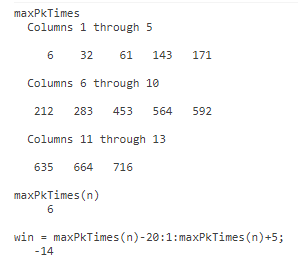

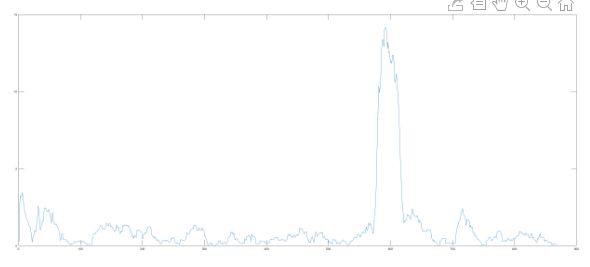

need to set a parameter that the peak is at least window size away from the edge. Adding now.

Adding this as the conditional

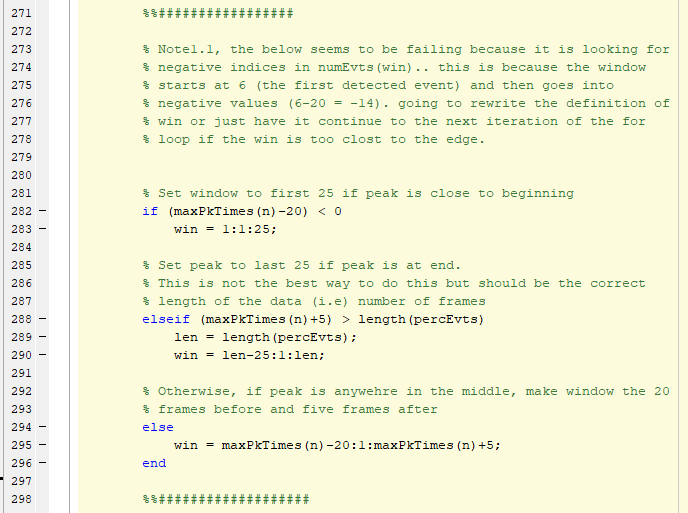

[bursts, burstStats] = detectBurst(features, spRes, tres, outDir);

allEvtLocs:
       47636
       47637
       48139
       48640
       48641
       48642
       48643
       49138
       49140
       49141

uLocs:
         836
        1127
        1338
        1628
        1629
        1841
        1842
        2130
        2131
        2132

length tlocs is: 795
tlocs{1}(1:10)
   581
   581
   581
   581
   581
   581
   581
   581
   581
   581

uT #1 is:
   581
   582
   583
   584
   585
   586
   587
   588
   589
   590
   591
   592
   593
   594
   595
   596
   597
   598
   599
   600
   601
   602
   603
   604
   605
   606
   607
   608
   609
   610
   611
   612
   613
   614
   615
   616
   617

sizeT is:
   795   870

here1
xPeaks is
  Columns 1 through 3

    3.4493    2.5895    1.4212

  Columns 4 through 6

    1.4566    1.3504    1.2442

  Columns 7 through 9

    1.3453    1.1380    1.4667

  Columns 10 through 12

   14.1562    2.3872    1.0419

  Column 13

    2.4024

Num elements in xPeaks is 13
____________
_____here2___

Unable to perform assignment because the size of the left side is 1-by-1 and the size of the right side is 1-by-0.

Error in detectBurst (line 306)
            bursts{jj}(n,1) = ixPre; %frame when burst rose 10%

got past the last error...on to the next

[bursts, burstStats] = detectBurst(features, spRes, tres, outDir);

_____here2_______
___Burst detected____
All burst event times (maxPkTimes)
  Columns 1 through 5

     6    32    61   143   171

  Columns 6 through 10

   212   283   453   564   592

  Columns 11 through 13

   635   664   716

n is
     1

win is
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10
    11
    12
    13
    14
    15
    16
    17
    18
    19
    20
    21
    22
    23
    24
    25

numEvts(win)
     4
    25
     7
     9
     2
     8
     4
     2
     3
     1
     0
     2
     1
     2
     2
     1
     3
     1
     0
     0
     0
     0
     1
     1
     2

_____issue here______
ixPre
     1

bursts{jj}(n,1)
     1

_____here2_______
___Burst detected____
All burst event times (maxPkTimes)
  Columns 1 through 5

     6    32    61   143   171

  Columns 6 through 10

   212   283   453   564   592

  Columns 11 through 13

   635   664   716

n is
     2

win is
    12
    13
    14
    15
    16
    17
    18
    19
    20
    21
   

Unable to perform assignment because the size of the left side is 1-by-1 and the size of the right side is 1-by-0.

Error in detectBurst (line 333)
            bursts{jj}(n,1) = ixPre; %frame when burst rose 10%

looks like it is failing as it is detecting a peak during a decent (at x = 61)

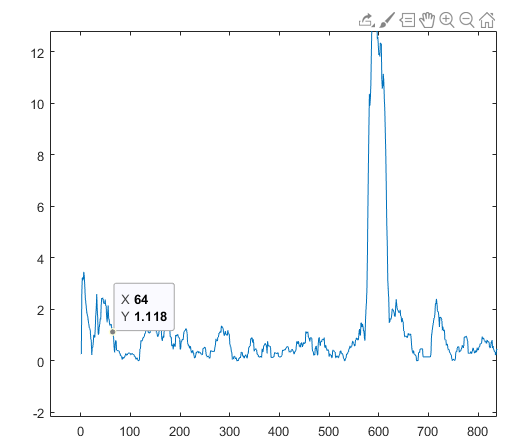

so if you look for ixPre in this scenario you cant find it - should be where burst rose 10%

weird as this is comming from signalprocessing toolbox `findpeaks` 

Going to try plotting percEvts with detected peak times

_____here2_______
Plotting percEvts


___Burst detected____
All burst event times (maxPkTimes)
  Columns 1 through 5

     6    32    61   143   171

  Columns 6 through 10

   212   283   453   564   592

  Columns 11 through 13

   635   664   716

n is
     1

win is
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10
    11
    12
    13
    14
    15
    16
    17
    18
    19
    20
    21
    22
    23
    24
    25

numEvts(win)
     4
    25
     7
     9
     2
     8
     4
     2
     3
     1
     0
     2
     1
     2
     2
     1
     3
     1
     0
     0
     0
     0
     1
     1
     2

_____issue here______
ixPre
     1

bursts{jj}(n,1)
     1

_____here2_______
Plotting percEvts


___Burst detected____
All burst event times (maxPkTimes)
  Columns 1 through 5

     6    32    61   143   171

  Columns 6 through 10

   212   283   453   564   592

  Columns 11 through 13

   635   664   716

n is
     2

win is
    12
    13
    14
    15
    16
    17
    18
    19
    20
    21
    22
    23
    24
    25
    26
    27
    28
    29
    30
    31
    32
    33
    34
    35
    36
    37

numEvts(win)
     2
     1
     2
     2
     1
     3
     1
     0
     0
     0
     0
     1
     1
     2
     1
     0
     1
     3
     4
     3
     9
     3
     1
     2
     2
     3

_____issue here______
ixPre
    22

bursts{jj}(n,1)
    22

_____here2_______
Plotting percEvts


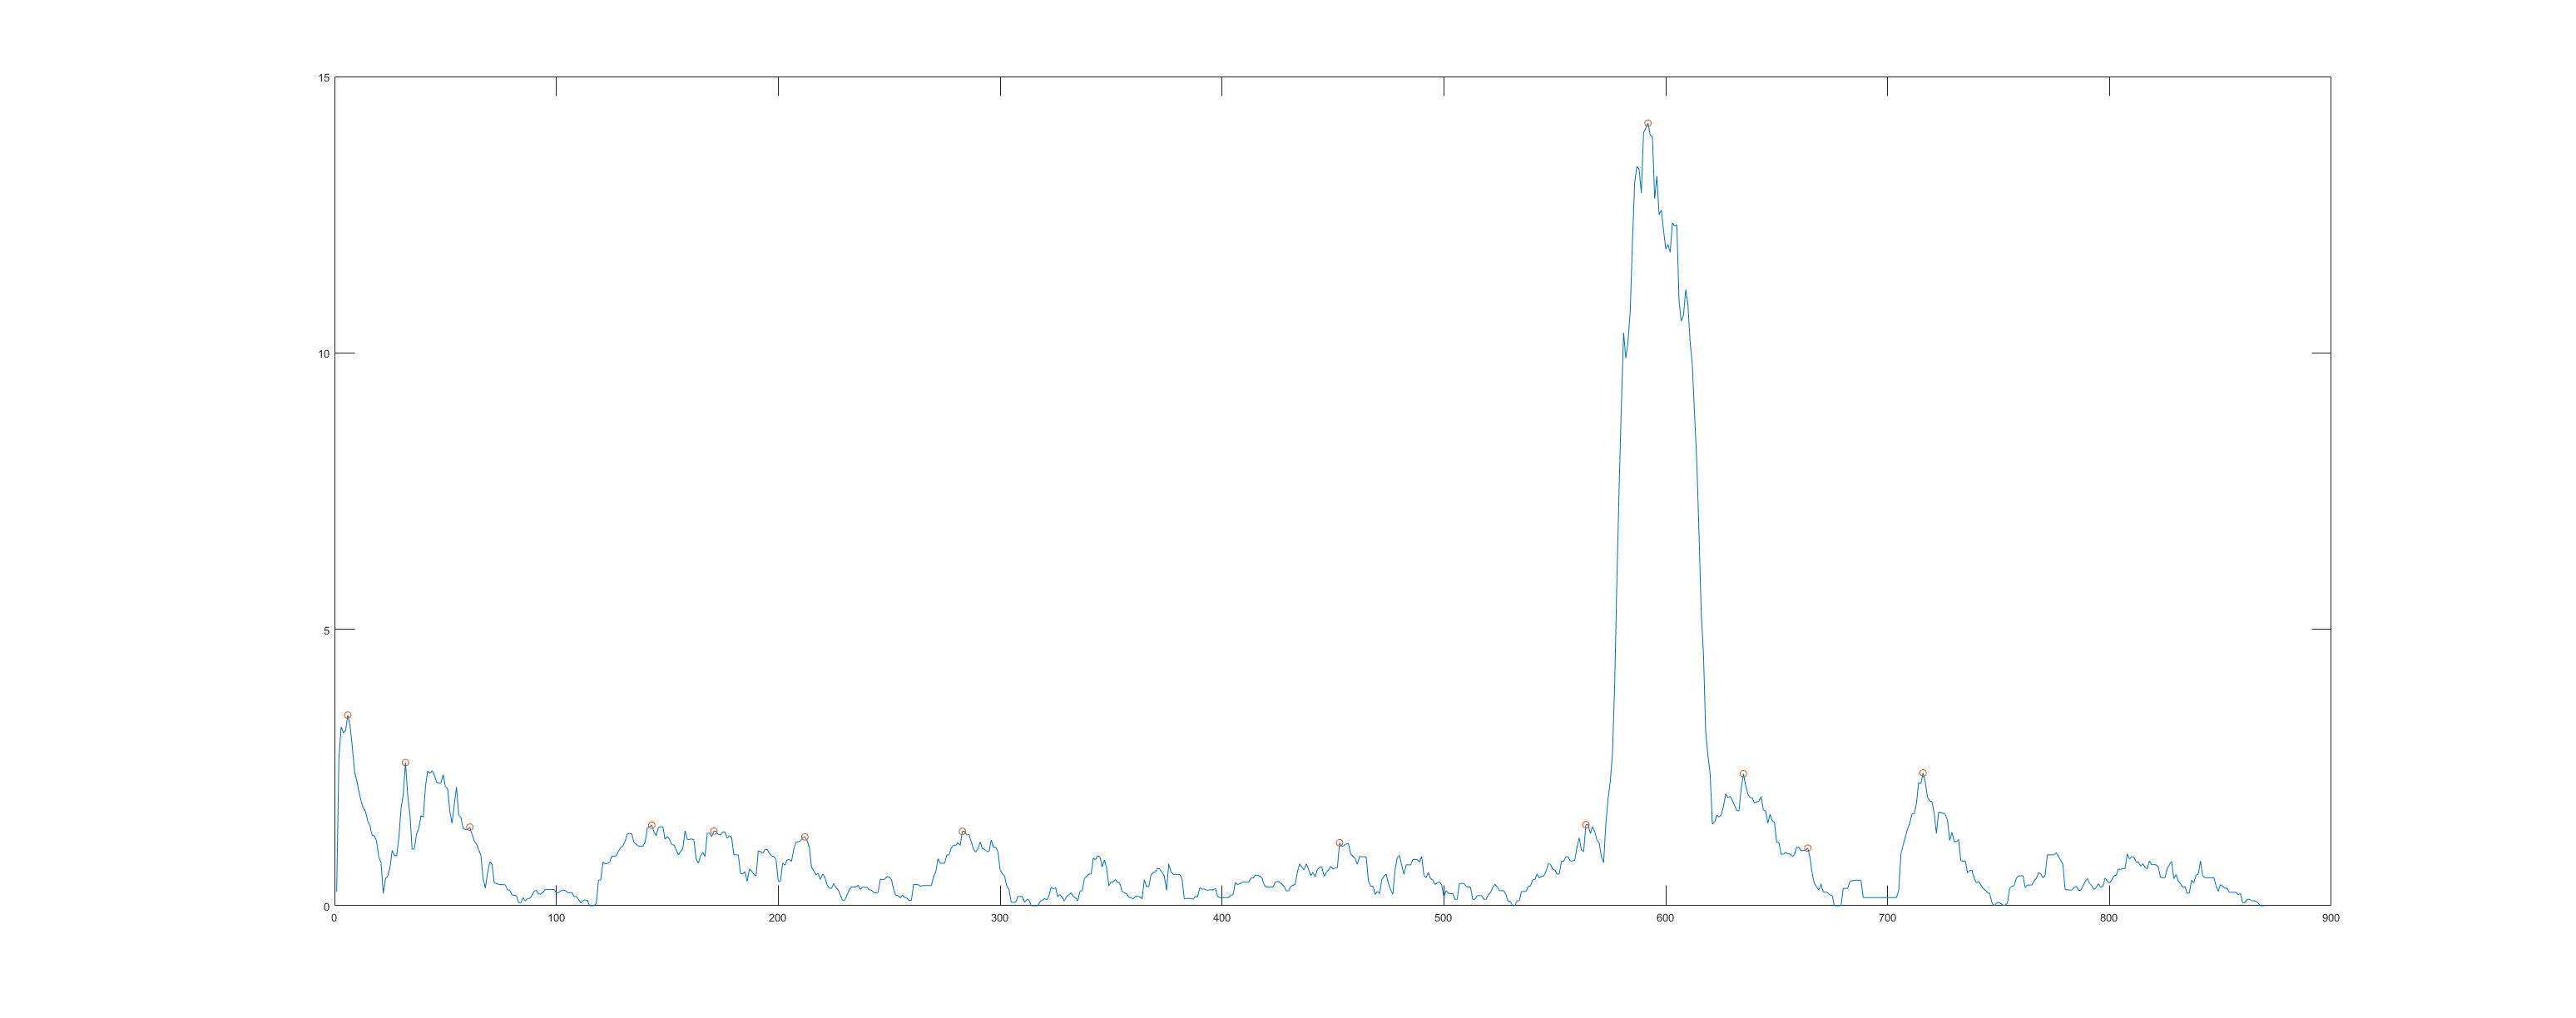

___Burst detected____
All burst event times (maxPkTimes)
  Columns 1 through 5

     6    32    61   143   171

  Columns 6 through 10

   212   283   453   564   592

  Columns 11 through 13

   635   664   716

n is
     3

win is
    41
    42
    43
    44
    45
    46
    47
    48
    49
    50
    51
    52
    53
    54
    55
    56
    57
    58
    59
    60
    61
    62
    63
    64
    65
    66

numEvts(win)
     2
     3
     0
     1
     1
     0
     2
     0
     1
     1
     1
     0
     0
     2
     1
     0
     0
     0
     0
     0
     1
     1
     0
     0
     0
     0

_____issue here______
ixPre


Unable to perform assignment because the size of the left side is 1-by-1 and the size of the right side is 1-by-0.

Error in detectBurst (line 348)
            bursts{jj}(n,1) = ixPre; %frame when burst rose 10%

[bursts, burstStats] = detectBurst(features, spRes, tres, outDir);

Here is the plot:

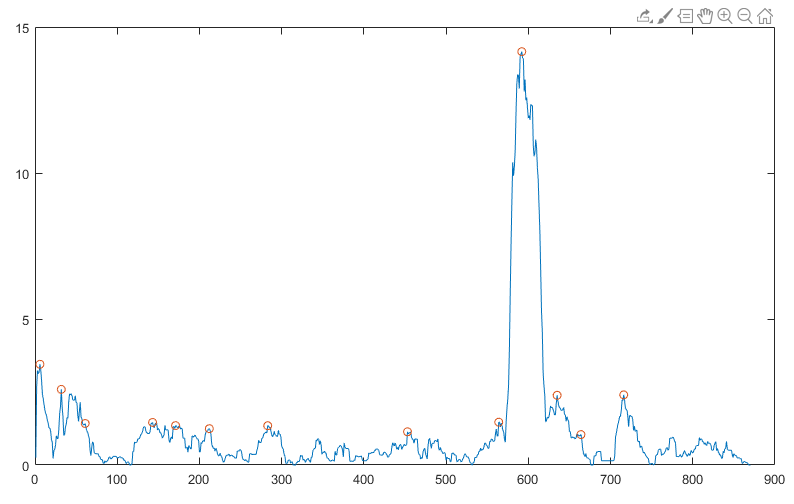

Looks like most of the peaks are good, need to determine why `findpeaks` from the SPT would detect n=3 as a peak. Detecting it as a peak is causing the issue with ixPre assignment as there is no period of 10% gain within the window testing 

One fix could be to just check ixPre != NULL  

Looking more into ix / pre / post

[bursts, burstStats] = detectBurst(features, spRes, tres, outDir);

_____here2_______
___Burst detected____
All burst event times (maxPkTimes)
  Columns 1 through 5

     6    32    61   143   171

  Columns 6 through 10

   212   283   453   564   592

  Columns 11 through 13

   635   664   716

n is
     1

win is
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10
    11
    12
    13
    14
    15
    16
    17
    18
    19
    20
    21
    22
    23
    24
    25

numEvts(win)
     4
    25
     7
     9
     2
     8
     4
     2
     3
     1
     0
     2
     1
     2
     2
     1
     3
     1
     0
     0
     0
     0
     1
     1
     2

______looking at ix________
xPeaks
  Columns 1 through 3

    3.4493    2.5895    1.4212

  Columns 4 through 6

    1.4566    1.3504    1.2442

  Columns 7 through 9

    1.3453    1.1380    1.4667

  Columns 10 through 12

   14.1562    2.3872    1.0419

  Column 13

    2.4024

xPeaks(n)
    3.4493

thrVec
    0.1000

xPeaks(n)*thrVec(1)
    0.3449

_____issue here______
ix
  Co

Unable to perform assignment because the size of the left side is 1-by-1 and the size of the right side is 1-by-0.

Error in detectBurst (line 381)
            bursts{jj}(n,1) = ixPre; %frame when burst rose 10%

Seems like there is an error in implementation here

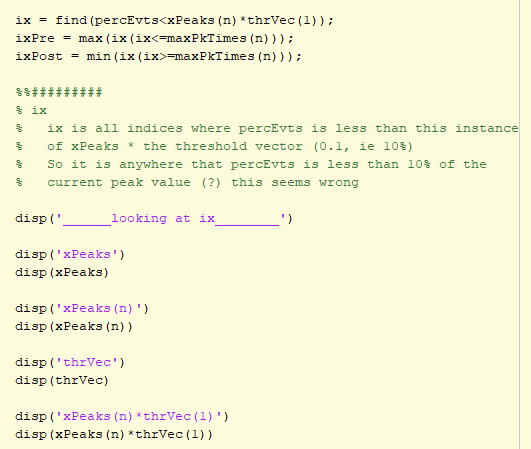

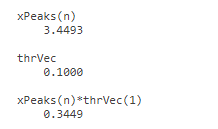

Actually, nevermind, this is a correct implementation (as expected from Nicole, haha) it is just that findpeaks is identifying a peak without anything previous that == 10% of its value

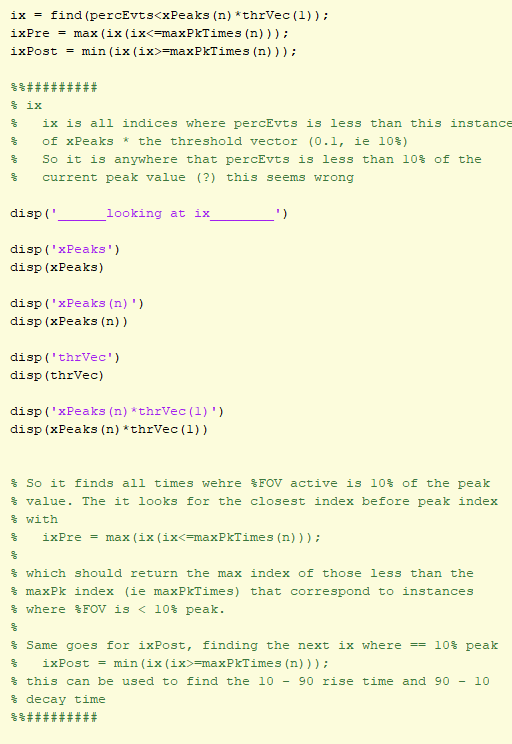

Again, see plot:

20.01.21 Continuing work here 

WIll start by implementing the restriction on rise / dcay times...see peak 3 above - this is where it is failing

[bursts, burstStats] = detectBurst(features, spRes, tres, outDir);

_____here2_______
___Burst detected____
All burst event times (maxPkTimes)
  Columns 1 through 5

     6    32    61   143   171

  Columns 6 through 10

   212   283   453   564   592

  Columns 11 through 13

   635   664   716

n is
     1

win is
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10
    11
    12
    13
    14
    15
    16
    17
    18
    19
    20
    21
    22
    23
    24
    25

numEvts(win)
     4
    25
     7
     9
     2
     8
     4
     2
     3
     1
     0
     2
     1
     2
     2
     1
     3
     1
     0
     0
     0
     0
     1
     1
     2

______looking at ix________
xPeaks
  Columns 1 through 3

    3.4493    2.5895    1.4212

  Columns 4 through 6

    1.4566    1.3504    1.2442

  Columns 7 through 9

    1.3453    1.1380    1.4667

  Columns 10 through 12

   14.1562    2.3872    1.0419

  Column 13

    2.4024

xPeaks(n)
    3.4493

thrVec
    0.1000

xPeaks(n)*thrVec(1)
    0.3449

_____issue here______
ix
  Co

Unable to perform assignment because the size of the left side is 1-by-1 and the size of the right side is 1-by-0.

Error in detectBurst (line 395)
            bursts{jj}(n,1) = ixPre; %frame when burst rose 10%

Side note (Note3.1):

    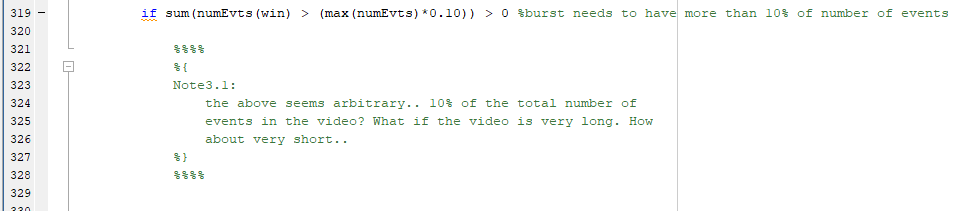

Going to work on this for a bit before proceeding to the peak detection issue... need a better definition of burst I think

[bursts, burstStats] = detectBurst(features, spRes, tres, outDir);

_____here2_______
n =
     1

_________More than 10%?_______
numEvts
     4
    25
     7
     9
     2
     8
     4
     2
     3
     1
     0
     2
     1
     2
     2
     1
     3
     1
     0
     0

length of numEvts
   870

win
  Columns 1 through 5

     1     2     3     4     5

  Columns 6 through 10

     6     7     8     9    10

  Columns 11 through 15

    11    12    13    14    15

  Columns 16 through 20

    16    17    18    19    20

  Columns 21 through 25

    21    22    23    24    25

numEvts(win)
  Columns 1 through 5

     4    25     7     9     2

  Columns 6 through 10

     8     4     2     3     1

  Columns 11 through 15

     0     2     1     2     2

  Columns 16 through 20

     1     3     1     0     0

  Columns 21 through 25

     0     0     1     1     2

_____issue here______
max peak time(n)
     6

ix 1:10
     1
    22
    68
    78
    79
    80
    81
    82
    83
    84

all previous ix == 0.1 peak
     1

ixPre
     1

ixPost


Unable to perform assignment because the size of the left side is 1-by-1 and the size of the right side is 1-by-0.

Error in detectBurst (line 443)
            bursts{jj}(n,1) = ixPre; %frame when burst rose 10%

So looks like numEvts is a record at each frome of the number of events (that started in? or are active in?) that frame 

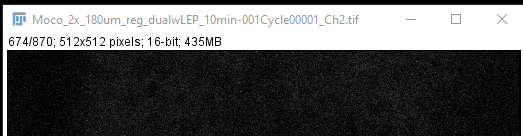

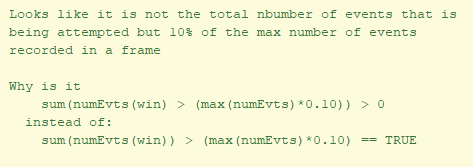

[bursts, burstStats] = detectBurst(features, spRes, tres, outDir);

_____here2_______
n =
     1

_________More than 10%?_______
numEvts
     4
    25
     7
     9
     2
     8
     4
     2
     3
     1
     0
     2
     1
     2
     2
     1
     3
     1
     0
     0

length of numEvts
   870

win
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10
    11
    12
    13
    14
    15
    16
    17
    18
    19
    20
    21
    22
    23
    24
    25

numEvts(win)
     4
    25
     7
     9
     2
     8
     4
     2
     3
     1
     0
     2
     1
     2
     2
     1
     3
     1
     0
     0
     0
     0
     1
     1
     2

sum(numEvts(win) > (max(numEvts)*0.10)) > 0
   1

sum(numEvts(win) > (max(numEvts)*0.10))
     8

sum(numEvts(win)
    81

(max(numEvts)*0.10))
    2.5000

_____issue here______
max peak time(n)
     6

ix 1:10
     1
    22
    68
    78
    79
    80
    81
    82
    83
    84

all previous ix == 0.1 peak
     1

ixPre
     1

ixPost
    22

bursts{jj}(n,1)
     1

_____here2_______
n =
  

Unable to perform assignment because the size of the left side is 1-by-1 and the size of the right side is 1-by-0.

Error in detectBurst (line 470)
            bursts{jj}(n,1) = ixPre; %frame when burst rose 10%

Looks like:

    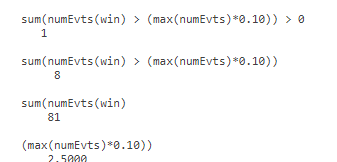

looking at number of frames (in this case 8) where the number of events was greater than 10% of the max number of events in the given window

Is maximum number of events really 25? Looks like that shows up in the second frame

Happened to fall in the window? Plotting num events....

_____here2_______
n =
     1

_________More than 10%?_______


numEvts
     4
    25
     7
     9
     2
     8
     4
     2
     3
     1
     0
     2
     1
     2
     2
     1
     3
     1
     0
     0

length of numEvts
   870

win
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10
    11
    12
    13
    14
    15
    16
    17
    18
    19
    20
    21
    22
    23
    24
    25

numEvts(win)
     4
    25
     7
     9
     2
     8
     4
     2
     3
     1
     0
     2
     1
     2
     2
     1
     3
     1
     0
     0
     0
     0
     1
     1
     2

sum(numEvts(win) > (max(numEvts)*0.10)) > 0
   1

sum(numEvts(win) > (max(numEvts)*0.10))
     8

sum(numEvts(win))
    81

(max(numEvts)*0.10))
    2.5000

_____issue here______
max peak time(n)
     6

ix 1:10
     1
    22
    68
    78
    79
    80
    81
    82
    83
    84

all previous ix == 0.1 peak
     1

ixPre
     1

ixPost
    22

bursts{jj}(n,1)
     1

_____here2_______
n =
     2

_________More than 10%?_______


numEvts
     4
    25
     7
     9
     2
     8
     4
     2
     3
     1
     0
     2
     1
     2
     2
     1
     3
     1
     0
     0

length of numEvts
   870

win
    12
    13
    14
    15
    16
    17
    18
    19
    20
    21
    22
    23
    24
    25
    26
    27
    28
    29
    30
    31
    32
    33
    34
    35
    36
    37

numEvts(win)
     2
     1
     2
     2
     1
     3
     1
     0
     0
     0
     0
     1
     1
     2
     1
     0
     1
     3
     4
     3
     9
     3
     1
     2
     2
     3

sum(numEvts(win) > (max(numEvts)*0.10)) > 0
   1

sum(numEvts(win) > (max(numEvts)*0.10))
     7

sum(numEvts(win))
    48

(max(numEvts)*0.10))
    2.5000

_____issue here______
max peak time(n)
    32

ix 1:10
     1
    22
    80
    81
    82
    83
    84
    85
    86
    87

all previous ix == 0.1 peak
     1    22

ixPre
    22

ixPost
    80

bursts{jj}(n,1)
    22

_____here2_______
n =
     3

_________More than 10%?_______


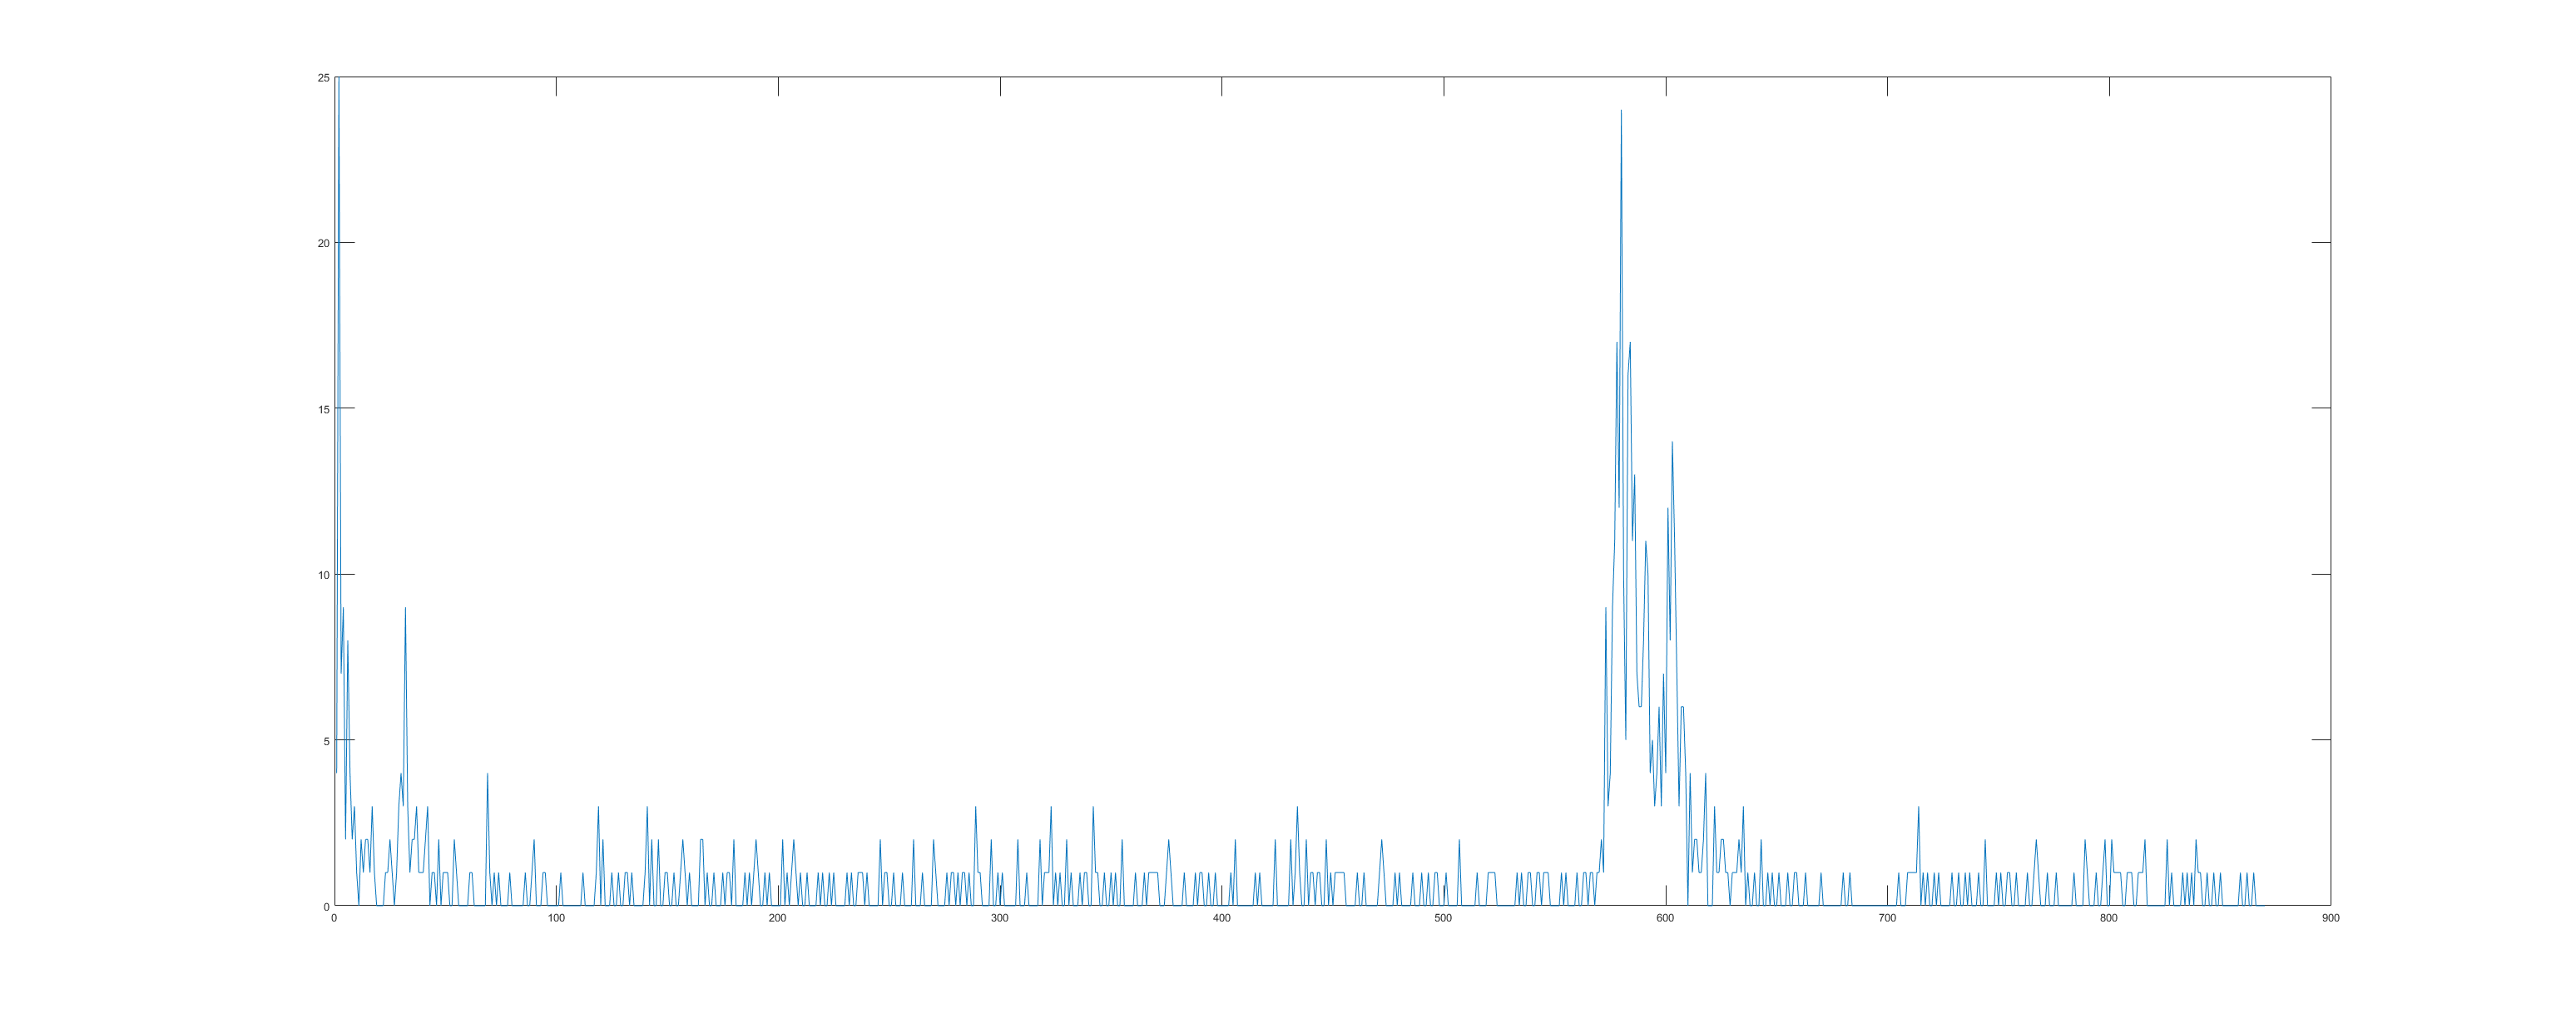

numEvts
     4
    25
     7
     9
     2
     8
     4
     2
     3
     1
     0
     2
     1
     2
     2
     1
     3
     1
     0
     0

length of numEvts
   870

win
    41
    42
    43
    44
    45
    46
    47
    48
    49
    50
    51
    52
    53
    54
    55
    56
    57
    58
    59
    60
    61
    62
    63
    64
    65
    66

numEvts(win)
     2
     3
     0
     1
     1
     0
     2
     0
     1
     1
     1
     0
     0
     2
     1
     0
     0
     0
     0
     0
     1
     1
     0
     0
     0
     0

sum(numEvts(win) > (max(numEvts)*0.10)) > 0
   1

sum(numEvts(win) > (max(numEvts)*0.10))
     1

sum(numEvts(win))
    17

(max(numEvts)*0.10))
    2.5000

_____issue here______
max peak time(n)
    61

ix 1:10
    83
    84
    86
    87
    88
   110
   111
   112
   113
   114

all previous ix == 0.1 peak
ixPre
ixPost
    83



Unable to perform assignment because the size of the left side is 1-by-1 and the size of the right side is 1-by-0.

Error in detectBurst (line 477)
            bursts{jj}(n,1) = ixPre; %frame when burst rose 10%

[bursts, burstStats] = detectBurst(features, spRes, tres, outDir);

So yes

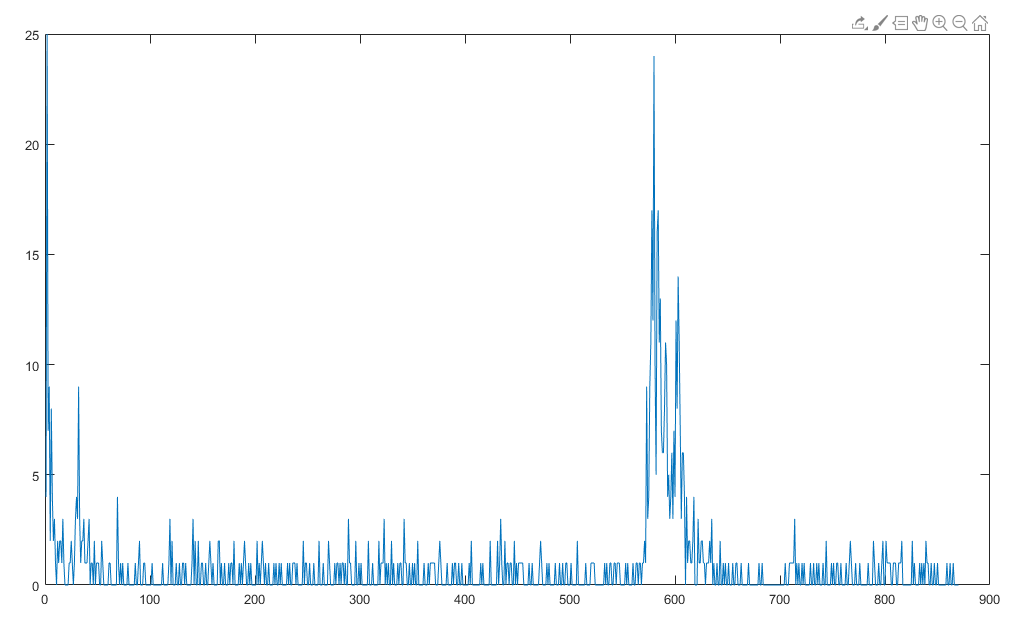

This might be thrown off by a wildcard.. looks like it picks up the burst at 600 as well

Should the beginnings and end of data be cut out??

Maybe will try with over 2x the average number of events? 2x baseline??) 

Should I write code to define baseline?? 

Also ... should detect bursts be limited to 1 video?? Then make detect burts batch?

    Actually no... as this is  it will handle solo vids as well as multiples

going to add baseline section:

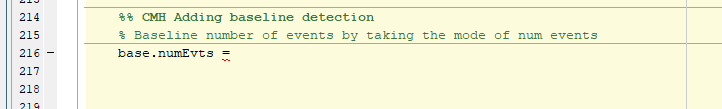

First will add baseline of number events by finding mode of number of events

a = [1,2,2,3,3,3,4,4,4,4,5,5,5,5,-1,-2]

a =      1     2     2     3     3     3     4     4     4     4     5     5     5     5    -1    -2


mode(a)

ans = 4

so it finds 4, is it lowest or first..

b = [1,2,2,3,3,3,7,7,7,7,4,4,4,4,5,5,5,5,-1,-2]

b =      1     2     2     3     3     3     7     7     7     7     4     4     4     4     5     5     5     5    -1    -2


mode(b)

ans = 4

it finds the lowest.. this works

lowest or closest to 0?

c = [-5,-5,-5,-5,1,2,2,3,3,3,7,7,7,7,4,4,4,4,5,5,5,5,-1,-2]

c =     -5    -5    -5    -5     1     2     2     3     3     3     7     7     7     7     4     4     4     4     5     5     5     5    -1    -2


mode(c)

ans = -5

looks like lowest.... should be fine for this purpose as there wont be a negative number of events

Adding mode numEvts 

note:: switching to `CdetectBursts` for editing further -- path issues

[bursts, burstStats] = CdetectBurst(features, spRes, tres, outDir);

___Start baseline___
length percEvts
   870

length(numEvts_mode)
   359

sum(numEvts == base.numEvts)
   241

length(percEvts_mode)
   241

percEvents_mode average
    0.9051

_____here2_______
n =
     1

_________More than 10%?_______
numEvts
     4
    25
     7
     9
     2
     8
     4
     2
     3
     1
     0
     2
     1
     2
     2
     1
     3
     1
     0
     0

length of numEvts
   870

win
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10
    11
    12
    13
    14
    15
    16
    17
    18
    19
    20
    21
    22
    23
    24
    25

numEvts(win)
     4
    25
     7
     9
     2
     8
     4
     2
     3
     1
     0
     2
     1
     2
     2
     1
     3
     1
     0
     0
     0
     0
     1
     1
     2

sum(numEvts(win) > (max(numEvts)*0.10)) > 0
   1

sum(numEvts(win) > (max(numEvts)*0.10))
     8

sum(numEvts(win))
    81

(max(numEvts)*0.10))
    2.5000

_____issue here______
max peak time(n)
     6

ix 1:10
     1

Unable to perform assignment because the size of the left side is 1-by-1 and the size of the right side is 1-by-0.

Error in CdetectBurst (line 532)
            bursts{jj}(n,1) = ixPre; %frame when burst rose 10%

Looks like it works

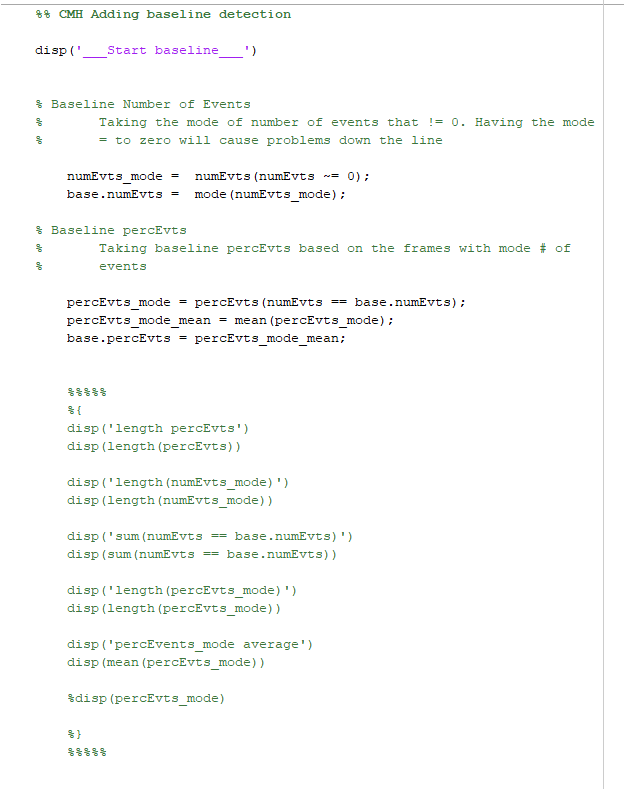

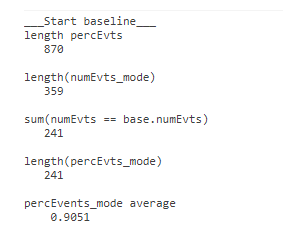

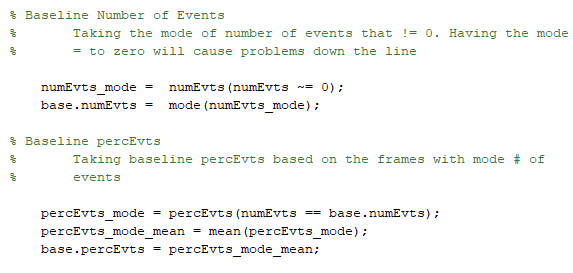

Modifying burst detection parameters to include:

    (Original) 

20.01.24 - have made a number of changes to the script including adding more test parameters for detecting bursts

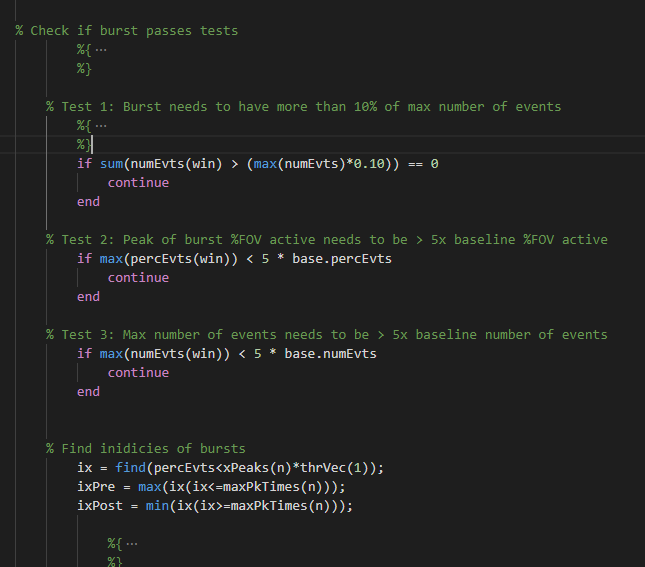

Testing...

[bursts, burstStats] = CdetectBurst(features, spRes, tres, outDir);

_____issue here______
max peak time(n)
   592

ix 1:10
     1
    17
    18
    19
    20
    21
    22
    23
    24
    25

all previous ix == 0.1 peak
  Columns 1 through 7

     1    17    18    19    20    21    22

  Columns 8 through 14

    23    24    25    26    27    28    29

  Columns 15 through 21

    35    36    37    38    58    59    60

  Columns 22 through 28

    62    63    64    65    66    67    68

  Columns 29 through 35

    69    70    71    72    73    74    75

  Columns 36 through 42

    76    77    78    79    80    81    82

  Columns 43 through 49

    83    84    85    86    87    88    89

  Columns 50 through 56

    90    91    92    93    94    95    96

  Columns 57 through 63

    97    98    99   100   101   102   103

  Columns 64 through 70

   104   105   106   107   108   109   110

  Columns 71 through 77

   111   112   113   114   115   116   117

  Columns 78 through 84

   118   119   120   121   122   123   124

  Columns 85 through 

Unrecognized function or variable 'numEvts'.

Error in CdetectBurst (line 32)
                numEvts_mode =  numEvts(numEvts ~= 0);

_______________________________________________________________________

Ran into infinite looping error and had to restart matlab

trying again.. have to rerun readFts etc

## Defining directories

You need to add AQuA to your path in order to use its functions

softwareDir = 'Z:/.code/AQuA/'; %AQuA path
addpath(genpath(softwareDir));

%  read features from movies and put all the information in one structure called out
datDir = 'data/processed/v26/v26.aqua.data/'; %input directory where all of your processed movies are (aqua's .mat)
outDir = 'interim/v26.interim/';

spRes = 0.57998046875; %um/pix
tres = 0.55578697729921; %sec/frame

## Read features from all movies, store in a structure called out

% you might need to rewrite parts of this function or use your own function
% for reading in the data. When I was doing this analysis, we had AQuA
% writing the output in a strucutre called res. One layer deep was a
% substructure called fts and a layer deeper into fts was substructures like
% propagation, network, etc. The output format has changed a bit
% over time, so this function might be a little outdated. 

disp(pwd)
out = readFts(datDir);

## PROPAGATION DIRECTION OVER TIME, single event example

%similar to figure 4c, top right. plot the event and its propagation
%direction over time

clear xLoc3D yLoc3D zLoc3D
for ii = 1:length(out.dff)
    for i = 1:length(out.locAbs{ii})
        aLocs = out.locAbs{ii}{i}; %single event
        [xLoc2D{ii}{i} yLoc2D{ii}{i} zLoc2D{ii}{i}] = (ind2sub([out.xSize{ii} out.ySize{ii} out.zSize{ii}], aLocs));
        xLoc2D{ii}{i} = out.xSize{ii}-xLoc2D{ii}{i};
    end
end

%index a single example event
ii=6; %movie index
j=3;  %burst index
i=44; %event index


plot(yLoc2D{ii}{i},xLoc2D{ii}{i},'s','Color',[0 174/255 239/255]); hold on;
axis([0 out.xSize{ii} 0 out.ySize{ii}])

pIdxG = cell(1,length(bursts));
offsetFr = bursts{ii}(j,2);
pIdxG{ii}{j} = zeros(round(1000),2);
propG = cell2mat(out.propGrow{ii}(i));
propG(isnan(propG))=0;
uTime = unique(zLoc2D{ii}{i});

clear sizeP turnaround taIdx on off timeOn
on = uTime(1);
off = uTime(end);
timeOn = on:1:off;

for jj = 1:size(timeOn,2) %time points of event
    %first column, N/S; second column E/W
    jIdx = timeOn(jj);
    
    northTime = propG(jj,1)-propG(jj,2);
    eastTime = propG(jj,4)-propG(jj,3);
    
    pIdxG{ii}{j}(jIdx,1) = pIdxG{ii}{j}(jIdx,1) + northTime; % (-): south, (+): north
    pIdxG{ii}{j}(jIdx,2) = pIdxG{ii}{j}(jIdx,2) + eastTime; % (-): west, (+): east
end


on = find(pIdxG{ii}{j},1);
off = find(pIdxG{ii}{j}(:,1),1,'last');
N = length(on:off);
C = linspecer(N,'sequential');

colormap(C);colorbar


%location at first frame
ii=6; %movie index
j=3;  %burst index
i=44; %event index

uTimeValues = unique(zLoc2D{ii}{i});
zLocIdx = find(zLoc2D{ii}{i} == uTimeValues(1)); %first frame
k(1) = nanmean(xLoc2D{ii}{i}(zLocIdx));
k(2) = nanmean(yLoc2D{ii}{i}(zLocIdx));

count=0; 
%index variable naming and renaming a bit dumb
kk=6; %movie index
jj=3;  %burst index

for ii = 1:length(timeOn)

    j = timeOn(ii);
    if  nansum(pIdxG{kk}{jj}(j,:)) ~= 0
        iii=ii-count;
        cInd = round(timeOn - bursts{kk}(jj,1));
        color = C(iii,:);
        plot([k(2) k(2)+pIdxG{kk}{jj}(j,2)],[k(1) k(1)+pIdxG{kk}{jj}(j,1)],'-','LineWidth',2,'Color',color);
        hold on;
        k = [k(1)+pIdxG{kk}{jj}(j,1) k(2)+pIdxG{kk}{jj}(j,2)];
        
        if pIdxG{kk}{jj}(j,2) > 0
            marker = '>';
        elseif pIdxG{kk}{jj}(j,2) < 0
            marker = '<';
        else
            marker = 'o';
        end
        
        if pIdxG{kk}{jj}(j,1) > 0 && pIdxG{kk}{jj}(j,1) > pIdxG{kk}{jj}(j,2)
            marker = '^';
        elseif pIdxG{kk}{jj}(j,1) < 0
            marker = 'v';
        else
            marker = 'o';
        end
        
        axis([0 out.xSize{kk} 0 out.ySize{kk}]); hold on;
        plot(k(2), k(1), 'Marker',marker,'Color',color,'MarkerSize',5,'LineWidth',jj);
    else
        count=count+1;
    end
end


title('posterior')
xlabel('anterior')
ylabel('lateral')
colormap(C);
c=colorbar;
c.Ticks = [1/length(timeOn):1/length(timeOn):1];
for i = 1:length(timeOn)
    j = timeOn(i);
    ar(i) = {num2str(j)};
end
c.TickLabels = ar;
ylabel(c,'medial')
set(gca,'fontsize',18)